% Q1
A = [
    [0 1 0];
    [0 0 1];
    [-5 -25 -5]]

A =      0     1     0
     0     0     1
    -5   -25    -5



B = [0; 25;-120]

B =      0
    25
  -120



C = [1 0 0];

D = 0

D = 0


% Can add a number
var = ss2tf(A,B,C,D)

var =          0         0   25.0000    5.0000



s = tf("s")

s =
 
  s
 
Continuous-time transfer function.



G = 25*s + 5

G =
 
  25 s + 5
 
Continuous-time transfer function.




% Q2 (done in onenote)
x = 8:0.01:10

x =     8.0000    8.0100    8.0200    8.0300    8.0400    8.0500    8.0600    8.0700    8.0800    8.0900    8.1000    8.1100    8.1200    8.1300    8.1400    8.1500    8.1600    8.1700    8.1800    8.1900    8.2000    8.2100    8.2200    8.2300    8.2400    8.2500    8.2600    8.2700    8.2800    8.2900    8.3000    8.3100    8.3200    8.3300    8.3400    8.3500    8.3600    8.3700    8.3800    8.3900    8.4000    8.4100    8.4200    8.4300    8.4400    8.4500    8.4600    8.4700    8.4800    8.4900


y = 2:0.01:4

y =     2.0000    2.0100    2.0200    2.0300    2.0400    2.0500    2.0600    2.0700    2.0800    2.0900    2.1000    2.1100    2.1200    2.1300    2.1400    2.1500    2.1600    2.1700    2.1800    2.1900    2.2000    2.2100    2.2200    2.2300    2.2400    2.2500    2.2600    2.2700    2.2800    2.2900    2.3000    2.3100    2.3200    2.3300    2.3400    2.3500    2.3600    2.3700    2.3800    2.3900    2.4000    2.4100    2.4200    2.4300    2.4400    2.4500    2.4600    2.4700    2.4800    2.4900


z = x.^2 + 4*x.*y + 6*y.^2

z =   152.0000  152.8011  153.6044  154.4099  155.2176  156.0275  156.8396  157.6539  158.4704  159.2891  160.1100  160.9331  161.7584  162.5859  163.4156  164.2475  165.0816  165.9179  166.7564  167.5971  168.4400  169.2851  170.1324  170.9819  171.8336  172.6875  173.5436  174.4019  175.2624  176.1251  176.9900  177.8571  178.7264  179.5979  180.4716  181.3475  182.2256  183.1059  183.9884  184.8731  185.7600  186.6491  187.5404  188.4339  189.3296  190.2275  191.1276  192.0299  192.9344  193.8411



plot3(x,y,z)



% Q3 

% Hardset var
A1 = 20;
A2 = 15;
B1 = 1.1;
B2 = 1.5;


F01 = 1.75;
F02 = 2.86;

H1 = 6;
H2 = 3.5;


% f_1 = F01/A1 - B1/A1*sqrt(t-H2)

% f_2 = log(F02)/A2+B1/A2*sqrt(H1-t)-B2/A2*sqrt(t)
t_span = 0:0.01:5;

[t1,y1] = ode45(@ode1func,t_span, 6)

t1 =          0
    0.0100
    0.0200
    0.0300
    0.0400
    0.0500
    0.0600
    0.0700
    0.0800
    0.0900


y1 =     6.0000
    6.0000
    6.0000
    6.0000
    6.0000
    6.0000
    6.0000
    6.0000
    6.0000
    6.0000


[t2,y2] = ode45(@ode1func,t_span, 3.5)

t2 =          0
    0.0100
    0.0200
    0.0300
    0.0400
    0.0500
    0.0600
    0.0700
    0.0800
    0.0900


y2 =     3.5000
    3.5009
    3.5017
    3.5026
    3.5034
    3.5043
    3.5051
    3.5059
    3.5068
    3.5076


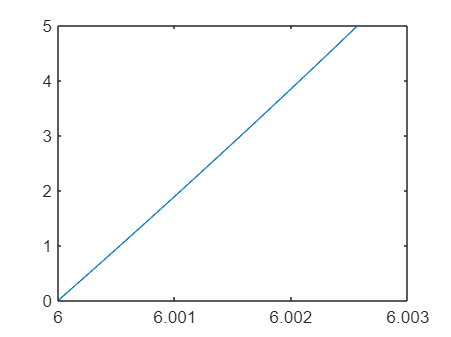


plot(y1,t1)

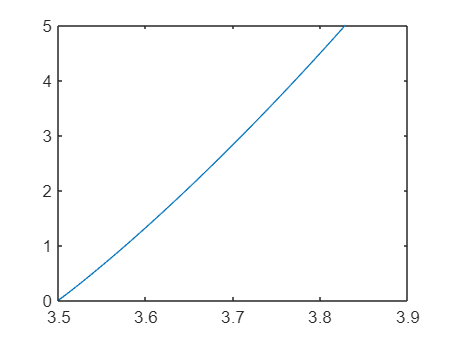

plot(y2,t2)



H1 = 6;
H2 = 3.5;

f_1 = F01/A1 - B1/A1*sqrt(H1-H2)

f_1 = 5.3736e-04


f_2 = log(F02)/A2+B1/A2*sqrt(H1-H2)-B2/A2*sqrt(H2)

f_2 = -0.0011




f01 = [0.5 0.8 1.25 1.5 1.75 2 2.25 2.75 3.5 4.75];
output_nl = zeros(length(f01))

output_nl =      0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0


output_l = zeros(length(f01))

output_l =      0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0



% for i = 1:length(f01);
%     F01 = f01(i);
%     F02 = 0;
%     

% Non-Linear functions
syms H1 H2 F01 F02

f1 = F01/A1 - B1/A1*sqrt(H1-H2)

$$f1 = \frac{F_{01}}{20}-\frac{11\,\sqrt{H_{1}-H_{2}}}{200}$$

f2 = log(F02)/A2+B1/A2*sqrt(H1-H2)-B2/A2*sqrt(H2)

$$f2 = \frac{\log\left(F_{02}\right)}{15}-\frac{\sqrt{H_{2}}}{10}+\frac{11\,\sqrt{H_{1}-H_{2}}}{150}$$


diff_A_11 = diff(f1,H1)

$$diff\_A\_11 = -\frac{11}{400\,\sqrt{H_{1}-H_{2}}}$$

diff_A_12 = diff(f1,H2)

$$diff\_A\_12 = \frac{11}{400\,\sqrt{H_{1}-H_{2}}}$$

diff_A_21 = diff(f2,H1)

$$diff\_A\_21 = \frac{11}{300\,\sqrt{H_{1}-H_{2}}}$$

diff_A_22 = diff(f2,H2)

$$diff\_A\_22 = -\frac{1}{20\,\sqrt{H_{2}}}-\frac{11}{300\,\sqrt{H_{1}-H_{2}}}$$

diff_B_11  =diff(f1,F01)

$$diff\_B\_11 = \frac{1}{20}$$

diff_B_12  =diff(f1,F02)

$$diff\_B\_12 = 0$$

diff_B_21  =diff(f2,F01)

$$diff\_B\_21 = 0$$

diff_B_22  =diff(f2,F02)

$$diff\_B\_22 = \frac{1}{15\,F_{02}}$$


F01 = 1.75;
F02 = 2.86;
    
H1 = 6;
H2 = 3.5;

diff_A_11 = double(vpa(subs(diff_A_11)))

diff_A_11 = -0.0174

diff_A_12 = double(vpa(subs(diff_A_12)))

diff_A_12 = 0.0174

diff_A_21 = double(vpa(subs(diff_A_21)))

diff_A_21 = 0.0232

diff_A_22 = double(vpa(subs(diff_A_22)))

diff_A_22 = -0.0499

diff_B_11 = double(vpa(subs(diff_B_11)))

diff_B_11 = 0.0500

diff_B_12 = double(vpa(subs(diff_B_12)))

diff_B_12 = 0

diff_B_21 = double(vpa(subs(diff_B_21)))

diff_B_21 = 0

diff_B_22 = double(vpa(subs(diff_B_22)))

diff_B_22 = 0.0233


A = [diff_A_11 diff_A_12;
     diff_A_21 diff_A_22]

A =    -0.0174    0.0174
    0.0232   -0.0499


B = [diff_B_11 diff_B_12;
     diff_B_21 diff_B_22]

B =     0.0500         0
         0    0.0233


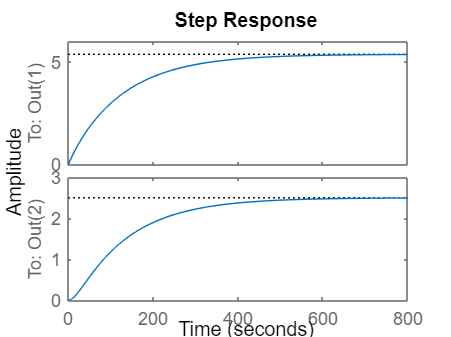

C = [1 0;
     0 1];
D = [0 0;
     0 0];

step(tf(ss(A,B(:,1),C,D(:,1))))

function dydt = ode1func(t,y)
    A1 = 20;
    A2 = 15;
    B1 = 1.1;
    B2 = 1.5;
    
    F01 = 1.75;
    F02 = 2.86;
    
    H1 = 6;
    H2 = 3.5;
    dydt = F01/A1 - B1/A1*sqrt(y-H2);
end

function dydt = ode2func(t,y)
    A1 = 20;
    A2 = 15;
    B1 = 1.1;
    B2 = 1.5;
    
    
    F01 = 1.75;
    F02 = 2.86;
    
    H1 = 6;
    H2 = 3.5;
    dydt = log(F02)/A2+B1/A2*sqrt(H1-y)-B2/A2*sqrt(y);
end






















